# Chapter 1

% create different types of matrices
z = zeros(5, 5)

z =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


class(z) % type of z

ans = 'double'


z = zeros(5, 5, 'uint16')

z = 5×5 uint16 matrix
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0


class(z)

ans = 'uint16'


i = eye(5, 5) % identity matrix

i =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1



one = ones(5, 5, 3)  % 5x5x3 ones matrix

one = one(:,:,1) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


one(:,:,2) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


one(:,:,3) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1



[r, c, ch] = size(one)  % shape of matrix

r = 5

c = 5

ch = 3

fprintf("rows = %d, cols = %d, channels = %d\n", r, c, ch) % printing to screen

rows = 5, cols = 5, channels = 3



r = randn(5, 5, 3)  % normally distributed random numbers

r = r(:,:,1) =

   -1.1842   -0.8645   -0.6987   -0.7726   -1.5672
    0.2816   -0.0551    0.8544   -0.6995    0.2499
    0.9143    0.9304   -0.2746   -1.2659   -0.9656
    0.4827   -0.7636    0.2229    1.1740   -0.1657
    0.3736   -1.2357   -1.7448    1.0399    0.0457


r(:,:,2) =

    1.7096    0.1383   -1.3023    0.6076   -1.6809
    0.3704    2.2422   -0.4115    0.9198    0.0378
   -0.6565   -0.1668   -0.5401    0.8994    1.6635
    0.8314   -0.4590    1.3665    0.0327    0.8310
    0.8760    0.5462    0.7068   -1.4159    1.0477


r(:,:,3) =

    1.7938    2.2000    0.7129   -1.5362    1.2731
   -0.4851    0.8906    1.1684    0.5762    0.9879
   -0.6336   -0.6354    0.3400    0.5721   -0.7119
    1.1019   -0.3735   -1.0147    0.1467   -1.3343
   -0.7170    0.5219    0.0931   -0.9257    1.0042



mn = mean(r, "all")  % mean of all elements

mn = 0.1003

mn_cols = mean(r)  % mean of each column

mn_cols = mn_cols(:,:,1) =

    0.1736   -0.3977   -0.3282   -0.1048   -0.4806


mn_cols(:,:,2) =

    0.6262    0.4602   -0.0361    0.2087    0.3798


mn_cols(:,:,3) =

    0.2120    0.5207    0.2599   -0.2334    0.2438



sd = std(r, [], "all")  % std of all values

sd = 0.9726

sd = std(r)  % row vector with std of each column

sd = sd(:,:,1) =

    0.7968    0.8566    0.9810    1.1284    0.7625


sd(:,:,2) =

    0.8644    1.0636    1.0627    0.9762    1.2904


sd(:,:,3) =

    1.1574    1.1284    0.8200    0.9520    1.1827




x = [1, 2, 3, NaN;
    NaN, 5, 5, 5;
    9, 0, NaN, 0]

x =      1     2     3   NaN
   NaN     5     5     5
     9     0   NaN     0


% replace NaN values with -1 using logical indexing
x(isnan(x)) = -1

x =      1     2     3    -1
    -1     5     5     5
     9     0    -1     0


% plot as image
r = randi(11, 11, 3)

r =      9     2     6
     6    11     1
     8     8     6
     9    11     1
     4     3    10
    11    10     7
     7     6     8
     4     7     8
     3     1     7
    10     7    11


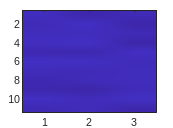

image(r, "Interpolation","bilinear")

r_1_7 = randi(7, [5, 9])

r_1_7 =      4     5     2     7     1     6     7     1     2
     6     7     5     4     4     3     5     2     6
     4     2     7     7     3     5     2     3     6
     6     3     3     3     3     3     6     3     2
     2     1     1     5     7     5     6     4     5


r_11_21 = randi([11, 21], 7)  % 7x7 random integers between 11 and 21

r_11_21 =     12    15    17    18    13    16    18
    18    13    13    17    13    21    12
    14    18    15    12    14    12    18
    18    20    20    15    21    11    17
    14    21    15    21    16    18    11
    18    16    21    11    19    21    19
    15    13    15    15    14    12    21


m = [1:99]

m =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t = datasample(m, 5, "Replace", false)  % select 5 elements at random without repetetion

t =     44    34     5    22    56


f_handle_sum = @max  % creating a function handle

f_handle_sum = function_handle with value:
    @max


f_handle_sum(5, 7)

ans = 7

m = [1, 2, 3;
    4, 5, 6]

m =      1     2     3
     4     5     6


m .^ 2  % element wise power, same rule for all element wise operations - .<op>

ans =      1     4     9
    16    25    36


m .* [2, 0, 1]  % applies broadcasting

ans =      2     0     3
     8     0     6


fx = @(x1, x2, x3) (x1 ^ 2 + x2 ^ 3 + x3)  % using a function handle to create a function

fx = function_handle with value:
    @(x1,x2,x3)(x1^2+x2^3+x3)


fx(2, 1, 4)

ans = 9

kp_mask = [0, 0, 0, 0; ...
    0, 1, 1, 0; ...
    0, 0, 1, 1]

kp_mask =      0     0     0     0
     0     1     1     0
     0     0     1     1


one_pos = kp_mask ~= 0

one_pos = 3×4 logical array
   0   0   0   0
   0   1   1   0
   0   0   1   1


one_pos(:)

ans = 12×1 logical array
   0
   0
   0
   0
   1
   0
   0
   1
   1
   0


[r, c, v] = find(kp_mask == 1)  % find where == 1, row, col and the value (1 in this case)

r =      2
     2
     3
     3


c =      2
     3
     3
     4


v = 4×1 logical array
   1
   1
   1
   1


[r, c, v] = find(kp_mask)  % find row, col, values , where kp_mask is non-zero

r =      2
     2
     3
     3


c =      2
     3
     3
     4


v =      1
     1
     1
     1


help sum

 sum Sum of elements.
    S = sum(X) is the sum of the elements of the vector X. If X is a matrix,
    S is a row vector with the sum over each column. For N-D arrays, 
    sum(X) operates along the first non-singleton dimension.
 
    S = sum(X,"all") sums all elements of X.
 
    S = sum(X,DIM) sums along the dimension DIM.
 
    S = sum(X,VECDIM) operates on the dimensions specified in the vector 
    VECDIM. For example, sum(X,[1 2]) operates on the elements contained in
    the first and second dimensions of X.
 
    S = sum(...,OUTTYPE) specifies the type in which the 
    sum is performed, and the type of S. Available options are:
 
    "double"    -  S has class double for any input X
    "native"    -  S has the same class as X
    "default"   -  If X is floating point, that is double or single,
                   S has the same class as X. If

help std

 std Standard deviation.
    For vectors, Y = std(X) returns the standard deviation.  For matrices,
    Y is a row vector containing the standard deviation of each column.  For
    N-D arrays, std operates along the first non-singleton dimension of X.
 
    std normalizes Y by N-1 if N>1, where N is the sample size.  This is
    the sqrt of an unbiased estimator of the variance of the population
    from which X is drawn, as long as X consists of independent,
    identically distributed samples. For N=1, Y is normalized by N.
 
    Y = std(X,1) normalizes by N and produces the square root of the second
    moment of the sample about its mean.  std(X,0) is the same as std(X).
 
    Y = std(X,W) computes the standard deviation using the weight vector W.
    W typically contains either counts or inverse variances.  The length of
    W must equal the lengt